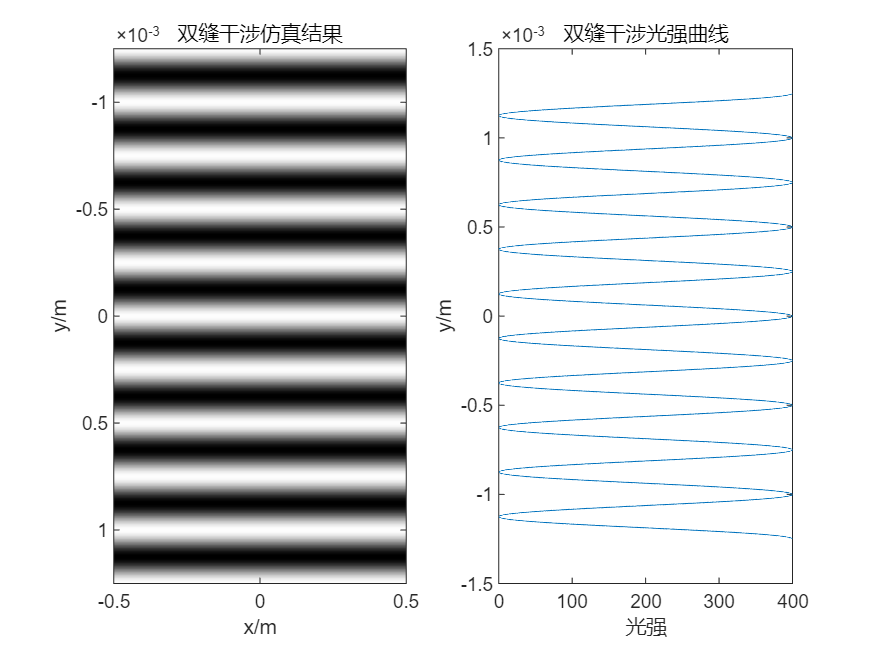

%杨氏干涉
clc;
clear all;
%基本参数
Lambda = 500;
Lambda = Lambda*(1e-9);
d = 2;
d = d*(1e-3);
D = 1;
yMax = 5*Lambda*D/d;
Ny = 10001;
viewScreenY = linspace(-yMax,yMax,Ny);
U1 = 10;
U2 = 10;
for n = 1:Ny
    r1 = sqrt((viewScreenY(n)-d/2).^2+D^2);
    r2 = sqrt((viewScreenY(n)+d/2).^2+D^2);
    phiDiff = (2*pi/Lambda)*(r1-r2);
    I(n,:) = (U1/r1)^2+(U2/r2)^2+2*U1*U2*cos(phiDiff)/(r1*r2);
end

NCLevels = 255;
Br = (I/max(I))*NCLevels;
subplot(1,2,1);
image(0,viewScreenY,Br);
xlabel('x/m');ylabel('y/m');
colormap(gray(NCLevels));
title('双缝干涉仿真结果');
subplot(1,2,2);
plot(I(:),viewScreenY);
xlabel('光强');ylabel('y/m');
title('双缝干涉光强曲线');

%对比度
v = (max(I)-min(I))/(max(I)+min(I))

v = 1.0000

%平面波的叠加
Lambda = 500;
Lambda = Lambda*(1e-9);
A1 = 2;
A2 = 2;
